### Target: After obtaining the fitting results of $\Omega$ and $\Lambda$, we plot Fig.2b,e,h in the main text, in which process the overall scaling factor $c$ is given from simultaneous fitting of the following functions:

###  
$$\Omega/J=
\begin{cases}
c\sqrt{W_y},& W_y>0\\
0, & W_y<0.
\end{cases}
\\
\Lambda/J=
\begin{cases}
c\sqrt{\Gamma},& W_y>0\\
c(\sqrt{\Gamma}-\sqrt{-W_y}), & W_y<0.
\end{cases}$$


clear;clc
load xi_1_mean_ave10 %Determined from ten repetitive calibrations
load xi_1_lower_ave10 %Determined from ten repetitive calibrations
load xi_1_upper_ave10 %Determined from ten repetitive calibrations

load('Sy\omega.mat')
load('Sy\lambda.mat')

load('Sy\omega_upper_bound.mat') %from contour method
load('Sy\lambda_upper_bound.mat') %from contour method
load('Sy\omega_lower_bound.mat')%from contour method
load('Sy\lambda_lower_bound.mat')%from contour method

load('Sy\cc.mat')
load('Sy\dd.mat')   
load('Sy\S.mat')
load('Sy\S_uncert.mat')

load('J1.mat')  %The calibration results of J
load('J1_uncert.mat')

J1_seq=reshape(J1_seq,[70,1]);
mean(J1_seq)

ans = 1.4595e+03

max(J1_seq)

ans = 1.4992e+03

min(J1_seq)/max(J1_seq)

ans = 0.9571

J_bar=mean(J1_seq)*1e-3; %The average value of J, in kHz.
mean_omega=mean(omega)/J_bar;
mean_lambda=mean(lambda)/J_bar;

upperbar_omega=(max(omega_upper_bound)-mean(omega))/J_bar;   %from contour method
upperbar_lambda=(max(lambda_upper_bound)-mean(lambda))/J_bar; %from contour method
lowerbar_omega=(-min(omega_lower_bound)+mean(omega))/J_bar;   %from contour method
lowerbar_lambda=(-min(lambda_lower_bound)+mean(lambda))/J_bar; %from contour method

Plot Fig.2b

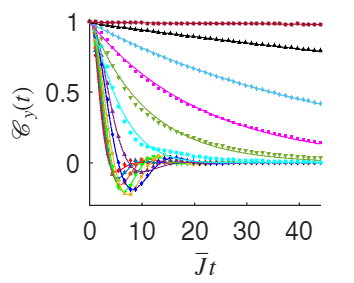

figure()
color={"#FF0000"
    "#0072BD"
    "#D95319"
    "#00FF00"
    "#EDB120"
    "#0000FF"
    "#7E2F8E"
    "#00FFFF"
    "#77AC30"
    "#FF00FF"
    "#4DBEEE"
    "#000000"
    "#A2142F"
    };
marker=flip({'.','^','d','s','v','.','^','d','s','v','.','^','d'});
markersize=flip([5,1,1,1,1,5,1,1,1,1,5,1,1])*1;
ii=1;
endpoint=41;
for i=1:13
    tau=5*1e-6;
    td1=41;
    quench_time_seq=24*tau*(0:td1-1)*1e3; %in ms

    x=quench_time_seq(1:endpoint);
    y=S(i,1:endpoint)';

    errorbar(x*2*pi*J_bar,y,FID_uncertainty(i,1:endpoint),marker{ii},'MarkerSize',markersize(ii),'MarkerFaceColor',color{ii},'Color',color{ii},'CapSize',1);
    hold on
    xx=0:1e-2:x(end);
    y_fit=cc(end,i)*cos(2*pi*omega(end,i)*xx+dd(end,i)).*exp(-2*pi*lambda(end,i)*xx);
    plot(2*pi*xx*J_bar,y_fit,'color',color{ii})
    ii=ii+1;
end

xlabel('$\bar{J}t$','Interpreter','latex','FontSize',15)
ylabel('$\mathcal{C}_y(t)$','Interpreter',"latex",'FontSize',15)
ylim([-0.3 1])
yticks([-0.5 0 0.5 1])
yticklabels({'-0.5', '0', '0.5', '1'})
xticks([0:10:50])
fontsize(gcf,10,'points')
fontname(gcf,"Helvetica")
set(gcf,'unit','centimeters','position',[10,10,5,4]);

set(gca,"box",'off')
saveas(gcf,'figures/b.pdf')

Simultaneous fitting to get $c$

xi_3=0.2;
xi_1=xi_1_mean';
xi_2=-xi_3-xi_1;

A=-6*xi_3.*xi_1;
B=xi_1.^2+xi_2.^2+xi_3.^2;

omega_theo=real(sqrt(A));
lambda_theo=sqrt(B)-(1-sign(A))/2.*sqrt(-A);

y=[mean_omega,mean_lambda]';
x=[omega_theo;lambda_theo];
[xData, yData] = prepareCurveData(x, y);

ft = fittype( 'c*x', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = 0.890903252535798;

[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      常规模型:
     fitresult(x) = c*x
     系数(置信边界为 95%):
       c =       0.914  (0.8512, 0.9769)

gof = 包含以下字段的 struct :
           sse: 0.0735
       rsquare: 0.9398
           dfe: 25
    adjrsquare: 0.9398
          rmse: 0.0542


conf=confint(fitresult)

conf =     0.8512
    0.9769


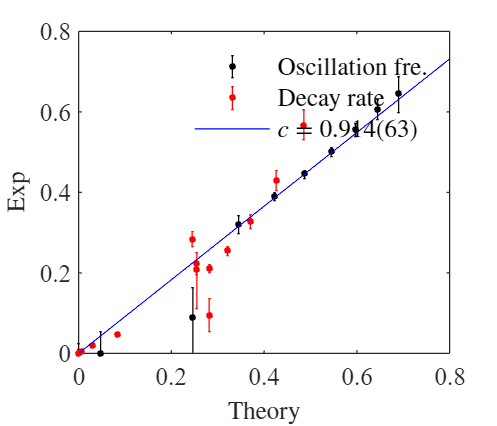

scale=fitresult.c;
scale_error=1/2*(conf(2)-conf(1));

figure()
errorbar(omega_theo,mean_omega,lowerbar_omega,upperbar_omega,...
    '.','Markersize',8,'color','k','CapSize',1)
hold on
errorbar(lambda_theo,mean_lambda,lowerbar_lambda,upperbar_lambda,...
    '.','Markersize',8,'color','r','CapSize',1)
hold on
plot(0:1e-3:1,fitresult(0:1e-3:1),'-','Color','b')

xlim([0 0.8])
ylim([0 0.8])
xlabel('Theory','Interpreter','latex')
ylabel('Exp','Interpreter','latex')

legend('Oscillation fre.','Decay rate',['$c=',num2str(round(scale,3)),'(',num2str(1e3*round(scale_error,3)),')$'],'interpreter','latex','box','off','fontsize',5)
fontsize(gcf,10,'points')
fontname(gcf,"Times New Roman")
set(gcf,'unit','centimeters','position',[10,10,7,6]);
set(gca,'XTickLabelRotation',0)

Plot Fig.2e

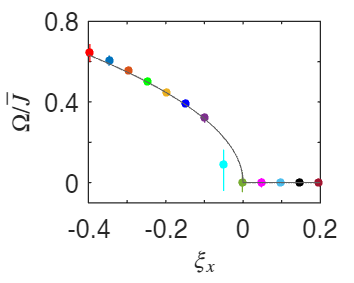

xi1_continuous=-0.4:1e-3:0.2;
xi_3=0.2;
xi_1=xi1_continuous';
xi_2=-xi_3-xi_1;

A=-6*xi_1.*xi_3;
B=xi_1.^2+xi_2.^2+xi_3.^2;

omega_fit=scale*real(sqrt(A));
lambda_fit=scale*sqrt(B)-(1-sign(A))/2.*sqrt(-A);

x=xi_1_mean';
y=mean_omega;
figure()
for i=1:13
    errorbar(x(i),y(i),lowerbar_omega(i),upperbar_omega(i),xi_1_lower(i),xi_1_upper(i),...
        '.','Markersize',10,'color',color{i},'Markerfacecolor',color{i},'CapSize',0)
    hold on
end
plot(xi1_continuous,omega_fit,'-','Color',[96 96 96]/255)

xlim([-0.4 0.2])
xticks([-0.4:0.1:0.2])
xticklabels({'-0.4','','-0.2','','0','','0.2'})
ylim([-0.1 0.8])
yticks([0:0.2:0.8])
yticklabels({'0','','0.4','','0.8'})
xlabel('$\xi_x$','Interpreter','latex')
ylabel('$\Omega/\bar{J}$','Interpreter','latex')

fontsize(gcf,10,'points')
fontname(gcf,"Helvetica")

set(gcf,'unit','centimeters','position',[10,10,5,4]);
set(gca,'XTickLabelRotation',0)
saveas(gcf,'figures/e.pdf')

Plot Fig.2h

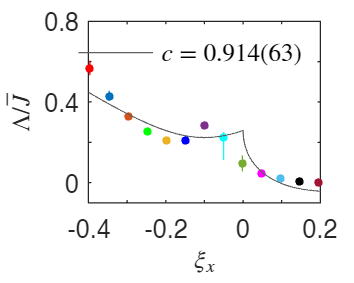

x=xi_1_mean';
y=mean_lambda;
figure()
for i=1:13
    errorbar(x(i),y(i),lowerbar_lambda(i),upperbar_lambda(i),xi_1_lower(i),xi_1_upper(i),...
        '.','Markersize',10,'color',color{i},'CapSize',0)
    hold on
end
plot(xi1_continuous,lambda_fit,'-','Color',[96 96 96]/255)
xlim([-0.4 0.2])
xticks([-0.4:0.1:0.2])
xticklabels({'-0.4','','-0.2','','0','','0.2'})
ylim([-0.1 0.8])
yticks([0:0.2:0.8])
yticklabels({'0','','0.4','','0.8'})
xlabel('$\xi_x$','Interpreter','latex')
ylabel('$\Lambda/\bar{J}$','Interpreter','latex')

legend('','','','','','','','','','','','','',['$c=',num2str(round(scale,3)),'(',num2str(1e3*round(scale_error,3)),')$'],'interpreter','latex','box','off')

fontsize(gcf,10,'points')
fontname(gcf,"Helvetica")

set(gcf,'unit','centimeters','position',[10,10,5,4]);
set(gca,'XTickLabelRotation',0)
saveas(gcf,'figures/h.pdf')